# Linear Model Predictive Control

Evaluation of the MPC given an input reference

**Note:** N represents the length of the prediction horizon.


$$$$ \dot{x} = A x + B u + C$$$$



$$x_i = \left[ \matrix{
y \cr 
v_y \cr 
\phi \cr 
r \cr 
} \right]_{4 \times 1} , \quad i \in [0, N]$$



$$u_i = \left[ \matrix{
\delta_{command}, 
M_{TV}
} \right]_{1 \times 2} , \quad i \in [0, N]$$


% Parameters of the MPC
N = 60;
n_states = 4;
n_inputs = 2;

### Reference vector

Reference states and (vx, psi) predicted from planner and previous step


$$x_0 = \left[ \matrix{
y_{0} \cr 
v_{y_{0}} \cr 
\phi_0 \cr 
r_0 \cr 
\delta_0 \cr
\dot{\delta}_0
} \right]_{6 \times 1} $$
     
$$x_{ref} = \left[ \matrix{
x_{{ref}_1} \cr 
x_{{ref}_2}  \cr 
\vdots \cr 
x_{{ref}_N} 
} \right]_{6N \times 1}$$


x_ref = [];
x_prev = [];
vx = [];

### Discrete model matrices for each step

A = cell(N,1);
B = cell(N,1);
C = cell(N,1);
for i = 1:N
    [A{i}, B{i}, C{i}] = direct_anfis_matrix(x_prev(i), x_ref(i));
end

Index exceeds array bounds.

### Model condinsing

Expressing the states as a function of the inputs and the initial state x_0.


$$X = \left[ \matrix{
x_1 \cr 
x_2 \cr 
\vdots \cr 
x_N 
} \right]_{6N \times 1}$$
          
$$U = \left[ \matrix{
u_0 \cr 
u_1 \cr 
\vdots \cr 
u_{N-1} 
} \right]_{N \times 1}$$



$$S = \left[ \matrix{
D & 0 & \cdots & 0 \cr
CD & D & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
C^{N-1}D & C^{N-2}D & \cdots & D
} \right]_{6N \times N}$$
              
$$T = \left[ \matrix{
C \cr 
C^2 \cr 
\vdots \cr 
C^N 
} \right]_{6N \times 6}$$



$$X = S \Delta U + T x_0$$



$$\left[ \matrix{
x_1 \cr 
x_2 \cr 
\vdots \cr 
x_N 
} \right]_{6N \times 1}
=
\left[ \matrix{
D & 0 & \cdots & 0 \cr
CD & D & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
C^{N-1}D & C^{N-2}D & \cdots & D 
} \right]_{6N \times N}
\left[ \matrix{
u_0 \cr 
u_1 \cr 
\vdots \cr 
u_{N-1} 
} \right]_{N \times 1}
+ 
\left[ \matrix{
C \cr 
C^2 \cr 
\vdots \cr 
C^N 
} \right]_{6N \times 6} x_0$$


C_powers = cell(1, mpc.n_horizon_ + 1);  % Pre-allocate a cell array for matrices
C_powers{1} = eye(mpc.n_states_);  % Initialize with the identity matrix

% Compute powers of matrix C
for i = 2:mpc.n_horizon_ + 1
    C_powers{i} = C_powers{i - 1} * C;
end

% Fill matrix T
for i = 1:mpc.n_horizon_
    T((mpc.n_states_ * (i - 1) + 1):(mpc.n_states_ * i), 1:mpc.n_states_) = C_powers{i + 1};
end

% Fill matrix S
for i = 1:mpc.n_horizon_
    for j = 1:i
        S((mpc.n_states_ * (i - 1) + 1):(mpc.n_states_ * i), j) = C_powers{i - j + 1} * D;
    end
end

The next step is to construct the Q and R matrices.


$$Q = \left[ \matrix{
q_y & 0 & 0 & 0 & 0 & 0\cr
0 & q_{vy} & 0 & 0 & 0 & 0\cr
0 & 0 & q_{\phi} & 0 & 0 & 0\cr
0 & 0 & 0 & q_r & 0 & 0\cr
0 & 0 & 0 & 0 & q_{\delta} & 0\cr
0 & 0 & 0 & 0 & 0 & q_{\dot{\delta}}\cr
} \right]_{6 \times 6}$$

$$P = \left[ \matrix{
p_y & 0 & 0 & 0 & 0 & 0\cr
0 & p_{vy} & 0 & 0 & 0 & 0\cr
0 & 0 & p_{\phi} & 0 & 0 & 0\cr
0 & 0 & 0 & p_r & 0 & 0\cr
0 & 0 & 0 & 0 & p_{\delta} & 0\cr
0 & 0 & 0 & 0 & 0 & p_{\dot{\delta}}\cr
} \right]_{6 \times 6}$$
     
$$R = \left[ \matrix{
r_{\delta_{command}} 
} \right]_{1 \times 1}$$



$$\overline{Q} = \left[ \matrix{
Q & 0 & \cdots & 0 \cr
0 & Q & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
0 & 0 & \cdots & P 
} \right]_{6N \times 6N}$$
            
$$\overline{R} = \left[ \matrix{
R & 0 & \cdots & 0 \cr
0 & R & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
0 & 0 & \cdots & R 
} \right]_{N \times N}$$


% Initialize Q matrix
Q = zeros(mpc.n_states_, mpc.n_states_);
Q(1, 1) = mpc.q_lat_;
Q(2, 2) = mpc.q_vy_;
Q(3, 3) = mpc.q_phi_;
Q(4, 4) = mpc.q_r_;
Q(5, 5) = mpc.q_delta_;
Q(6, 6) = mpc.r_delta_;

% Initialize P matrix
P = zeros(mpc.n_states_, mpc.n_states_);
P(1, 1) = mpc.p_lat_;
P(2, 2) = mpc.p_vy_;
P(3, 3) = mpc.p_phi_;
P(4, 4) = mpc.p_r_;
P(5, 5) = mpc.p_delta_;
P(6, 6) = mpc.r_delta_;

% Initialize R matrix
R = zeros(1, 1);
R(1, 1) = mpc.r_delta_command_;  % MATLAB uses 1-based indexing

% Create Q_ matrix
Q_ = zeros(mpc.n_horizon_ * mpc.n_states_, mpc.n_horizon_ * mpc.n_states_);
for i = 1:mpc.n_horizon_-1
    Q_((i-1)*mpc.n_states_+1:i*mpc.n_states_, (i-1)*mpc.n_states_+1:i*mpc.n_states_) = Q;
end
Q_((mpc.n_horizon_-1)*mpc.n_states_+1:mpc.n_horizon_*mpc.n_states_, (mpc.n_horizon_-1)*mpc.n_states_+1:mpc.n_horizon_*mpc.n_states_) = P;

% Create R_ matrix
R_ = zeros(mpc.n_horizon_, mpc.n_horizon_);
for i = 1:mpc.n_horizon_
    R_((i-1)+1:i, (i-1)+1:i) = R;
end

q_diag = diag(Q_);

The next step is to prepare the simulation by defining x_0 and x_ref.

% % Define file path and row to read
% csv_x0 = '/home/gil/bcnemotorsport/src/ltv_mpc/test/data/x0.csv';
% csv_xref = '/home/gil/bcnemotorsport/src/ltv_mpc/test/data/xref.csv';
% row_number = 5; 
% 
% % Read the entire CSV file (modify if necessary for large files)
% datax0 = readtable(csv_x0);
% dataxref = readtable(csv_xref);
% 
% % Extract data for x0
% x0_table = datax0(row_number, :);
% x0 = table2array(x0_table(:, 1:mpc.n_states_))';
% 
% % Extract data for x_ref
% x_ref_table = dataxref(row_number, :);
% x_ref = table2array(x_ref_table(:, 1:mpc.n_states_ * mpc.n_horizon_));
% x_ref = reshape(x_ref, mpc.n_states_, mpc.n_horizon_);
% x_ref = x_ref(:); % Flatten x_ref into a single column vector

x0 = zeros(mpc.n_states_, 1);
x0(1) = sim.x0.y;
x0(2) = sim.x0.vy;
x0(3) = sim.x0.phi;
x0(4) = sim.x0.r;
x0(5) = sim.x0.delta;
x0(6) = sim.x0.delta_dot;

% We are considering steady state references
x_ref_single = [
    sim.x_ref.y;
    sim.x_ref.vy;
    sim.x_ref.phi;
    sim.x_ref.r;
    sim.x_ref.delta;
    sim.x_ref.delta_dot
];

x_ref = zeros(mpc.n_states_ * mpc.n_horizon_, 1);
for i = 1:mpc.n_horizon_
    x_ref((i-1)*mpc.n_states_+1:i*mpc.n_states_) = x_ref_single;
end

### Model solution


$$H = 2(S^T\overline{Q}S + \overline{R})\;_{N \times N}$$



$$g^T = 2(x_0^T T^T - x_{ref}^T) \overline{Q}S \;_{N \times 1}$$



$$\Delta U^* = - H^{-1} g \;_{N \times 1}$$


% Construct Q*S
QS = Q_ * S;

% H matrix
H = 2 * (S' * QS + R_);
H = (H + H')/2;

% g vector
g = (2 * (x0' * T' - x_ref') * QS)';

% -------------- Optimization without restrictions ------------
% Calculate the result
% [L, D2, P] = ldl(H);
% 
% % Solve the system H * delta_u_opt = -g
% y = P * (-g);           % Permute -g based on the permutation matrix P
% z = L \ y;              % Solve L * z = y
% delta_u_opt = D2 \ z;     % Solve D * delta_u_opt = z
% delta_u_opt = L' \ delta_u_opt;  % Solve L' * delta_u_opt = previous result
% delta_u_opt = P' * delta_u_opt; % Apply the permutation to the result

% -------------- Optimization with restrictions ------------
f = g; % quadprog uses f instead of g

% Define bounds
lb = -ones(mpc.n_horizon_, 1) * mpc.max_steering_;
ub = ones(mpc.n_horizon_, 1) * mpc.max_steering_;

% Call quadprog
options = optimoptions('quadprog', 'Display', 'off');

[delta_u_opt, fval, exitflag] = quadprog(H, f, [], [], [], [], lb, ub, [], options);

% Check optimization status
if exitflag ~= 1
    warning('quadprog did not converge. Exitflag: %d', exitflag);
end

% Calculate the propagated states
pred_states = S * delta_u_opt + T * x0;

Results.

% Extract the first and fifth state from the predicted states
pred_state_y = pred_states(1:mpc.n_states_:end);
pred_state_vy = pred_states(2:mpc.n_states_:end);
pred_state_phi = pred_states(3:mpc.n_states_:end);
pred_state_r = pred_states(4:mpc.n_states_:end);
pred_state_delta = pred_states(5:mpc.n_states_:end);
pred_state_delta_dot = pred_states(6:mpc.n_states_:end);

% Extract the first and fifth reference values from x_ref
ref_state_y = x_ref(1:mpc.n_states_:end);
ref_state_vy = x_ref(2:mpc.n_states_:end);
ref_state_phi = x_ref(3:mpc.n_states_:end);
ref_state_r = x_ref(4:mpc.n_states_:end);
ref_state_delta = x_ref(5:mpc.n_states_:end);
ref_state_delta_dot = x_ref(6:mpc.n_states_:end);

% Append the x0 as the initial condition
pred_state_y = [x0(1); pred_state_y];
pred_state_vy = [x0(2); pred_state_vy];
pred_state_phi = [x0(3); pred_state_phi];
pred_state_r = [x0(4); pred_state_r];
pred_state_delta = [x0(5); pred_state_delta];
pred_state_delta_dot = [x0(6); pred_state_delta_dot];

ref_state_y = [x0(1); ref_state_y];
ref_state_vy = [x0(2); ref_state_vy];
ref_state_phi = [x0(3); ref_state_phi];
ref_state_r = [x0(4); ref_state_r];
ref_state_delta = [x0(5); ref_state_delta];
ref_state_delta_dot = [x0(6); ref_state_delta_dot];

delta_u_opt = [0; delta_u_opt];

% Time vector for the prediction horizon
time_horizon = 0:(mpc.n_horizon_);

figure;
subplot(3, 1, 1);
plot(time_horizon, pred_state_y, '-o', 'DisplayName', 'Predicted State y');
hold on;
plot(time_horizon, ref_state_y, '--', 'DisplayName', 'Reference State y');
xlabel('Time Step');
ylabel('State 1');
title('Evolution lateral error to the trajectory');
legend;
grid on;

subplot(3, 1, 2);
plot(time_horizon, pred_state_delta, '-o', 'DisplayName', 'Predicted State delta');
hold on;
plot(time_horizon, ref_state_delta, '--', 'DisplayName', 'Reference State delta');
plot(time_horizon, delta_u_opt, '-o', 'DisplayName', 'Input delta command');
xlabel('Time Step');
ylabel('State 5');
title('Evolution of Steering State');
legend;
grid on;

subplot(3, 1, 3);
plot(time_horizon, pred_state_delta_dot, '-o', 'DisplayName', 'Predicted State delta dot');
xlabel('Time Step');
ylabel('Input');
title('Evolution of Steering dot');
legend;
grid on;

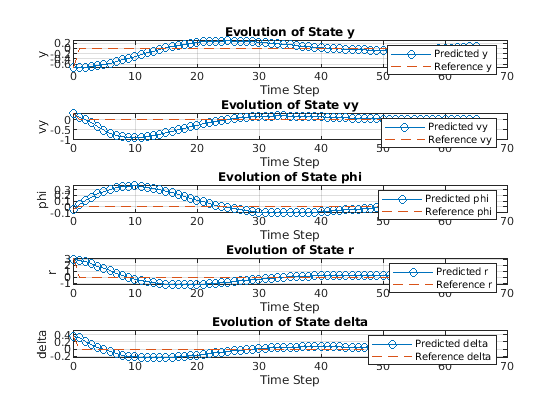

figure;

% Plot for state y
subplot(5, 1, 1);
plot(time_horizon, pred_state_y, '-o', 'DisplayName', 'Predicted y');
hold on;
plot(time_horizon, ref_state_y, '--', 'DisplayName', 'Reference y');
xlabel('Time Step');
ylabel('y');
title('Evolution of State y');
legend;
grid on;

% Plot for state vy
subplot(5, 1, 2);
plot(time_horizon, pred_state_vy, '-o', 'DisplayName', 'Predicted vy');
hold on;
plot(time_horizon, ref_state_vy, '--', 'DisplayName', 'Reference vy');
xlabel('Time Step');
ylabel('vy');
title('Evolution of State vy');
legend;
grid on;

% Plot for state phi
subplot(5, 1, 3);
plot(time_horizon, pred_state_phi, '-o', 'DisplayName', 'Predicted phi');
hold on;
plot(time_horizon, ref_state_phi, '--', 'DisplayName', 'Reference phi');
xlabel('Time Step');
ylabel('phi');
title('Evolution of State phi');
legend;
grid on;

% Plot for state r
subplot(5, 1, 4);
plot(time_horizon, pred_state_r, '-o', 'DisplayName', 'Predicted r');
hold on;
plot(time_horizon, ref_state_r, '--', 'DisplayName', 'Reference r');
xlabel('Time Step');
ylabel('r');
title('Evolution of State r');
legend;
grid on;

% Plot for state delta
subplot(5, 1, 5);
plot(time_horizon, pred_state_delta, '-o', 'DisplayName', 'Predicted delta');
hold on;
plot(time_horizon, ref_state_delta, '--', 'DisplayName', 'Reference delta');
xlabel('Time Step');
ylabel('delta');
title('Evolution of State delta');
legend;
grid on;